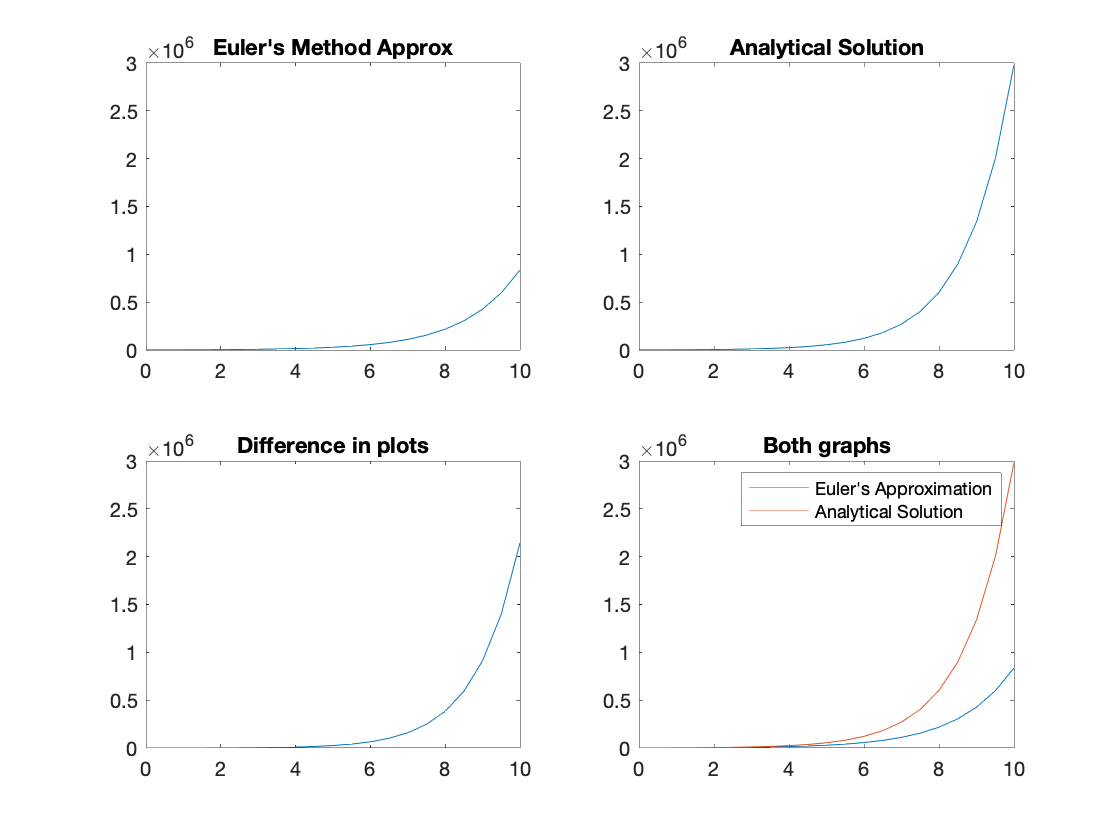

N0 = 1000;
N = N0;
r = 0.8;
h = 0.5;
t = 0;
ts = 0:h:10;
approx = [];
true_vec = [];

while t <= 10
    approx = [approx N];
    true_vec = [true_vec f(N0, r, t)];
    N = N + r * N * h;
    t = t + h;
end

subplot(2,2,1);
plot(ts, approx)
title("Euler's Method Approx")
ylim([0 3e6])

subplot(2,2,2);
plot(ts, true_vec)
title("Analytical Solution")

subplot(2,2,3)
plot(ts,(true_vec-approx))
ylim([0 3e6])
title("Difference in plots")

subplot(2,2,4)
plot(ts, approx, ts, true_vec)
title("Both graphs")
legend("Euler's Approximation", "Analytical Solution")


error = abs((approx(end)-true_vec(end))/true_vec(end))

error = 0.7193

function trueVal = f(N0, r, t)
    trueVal = N0 * exp(r * t);
end